# Channel Matched Filter Precoder Max Rate

% Downlink
% Max Rate V.S. Number of Antennas
% Linear and Rectangular Formation

## Global Parameter

clc;
clearvars;

Rtot = 10;
K = 10;
dn = 0.5;

M1 = [4, 8, 8, 16, 16];
M2 = [8, 8, 16, 16, 32];
M = M1 .* M2;
sample = 5;

time = 100;
cyclic_prefix = 20;

alpha = 0.0;
eta = 0;
mu = 0;


## Correlation Matrix

for index = 1 : sample
    for i = 1 : M(index)
        for j = 1 : M(index)
            dist(i, j) = abs(i - j) * dn;
        end
    end
    
    A = alpha .^ dist;
    exp_1D(index) = trace(A * A);
    clear A;
    
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    A = besseli(0, arg) ./ besseli(0, eta);
    bsl_1D(index) = trace(A * A');
    clear A;
end
clear dist;

for index = 1 : sample
    i = 1;
    for c1 = 1 : M1(index)
        for r1 = 1 : M2(index)
            j = 1;
            for c2 = 1 : M1(index)
                for r2 = 1 : M2(index)
                    dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                    j = j + 1;
                end
            end
            i = i + 1;
        end
    end
    dist = sqrt(dist .* dn);
    
    A = alpha .^ dist;
    exp_2D(index) = trace(A * A);
    clear A;
    
    arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
    arg = sqrt(arg);
    A = besseli(0, arg) ./ besseli(0, eta);
    bsl_2D(index) = trace(A * A');
    clear A;
end
clear dist;


## Required Power

factor = time / (time + cyclic_prefix);
r = 2 * Rtot / (K * factor);

for i = 1 : sample
    p0 = (K * (2 ^ r - 1)) / (M(i) - K * (2 ^ r - 1));
    dB0(i) = 10 * log10(p0);
    
    pc = (K * (2 ^ r - 1)) / (M(i));
    dBc(i) = 10 * log10(pc);
    
    nom = M(i) * K * (2 ^ r - 1);
    d1 = M(i) * M(i) - K * exp_1D(i) * (2 ^ r - 1);
    d2 = M(i) * M(i) - K * bsl_1D(i) * (2 ^ r - 1);
    d3 = M(i) * M(i) - K * exp_2D(i) * (2 ^ r - 1);
    d4 = M(i) * M(i) - K * bsl_2D(i) * (2 ^ r - 1);
    
    p1 = nom / d1;
    dB1(i) = 10 * log10(p1);
    
    p2 = nom / d2;
    dB2(i) = 10 * log10(p2);
    
    p3 = nom / d3;
    dB3(i) = 10 * log10(p3);
    
    p4 = nom / d4;
    dB4(i) = 10 * log10(p4);
end


## Plots

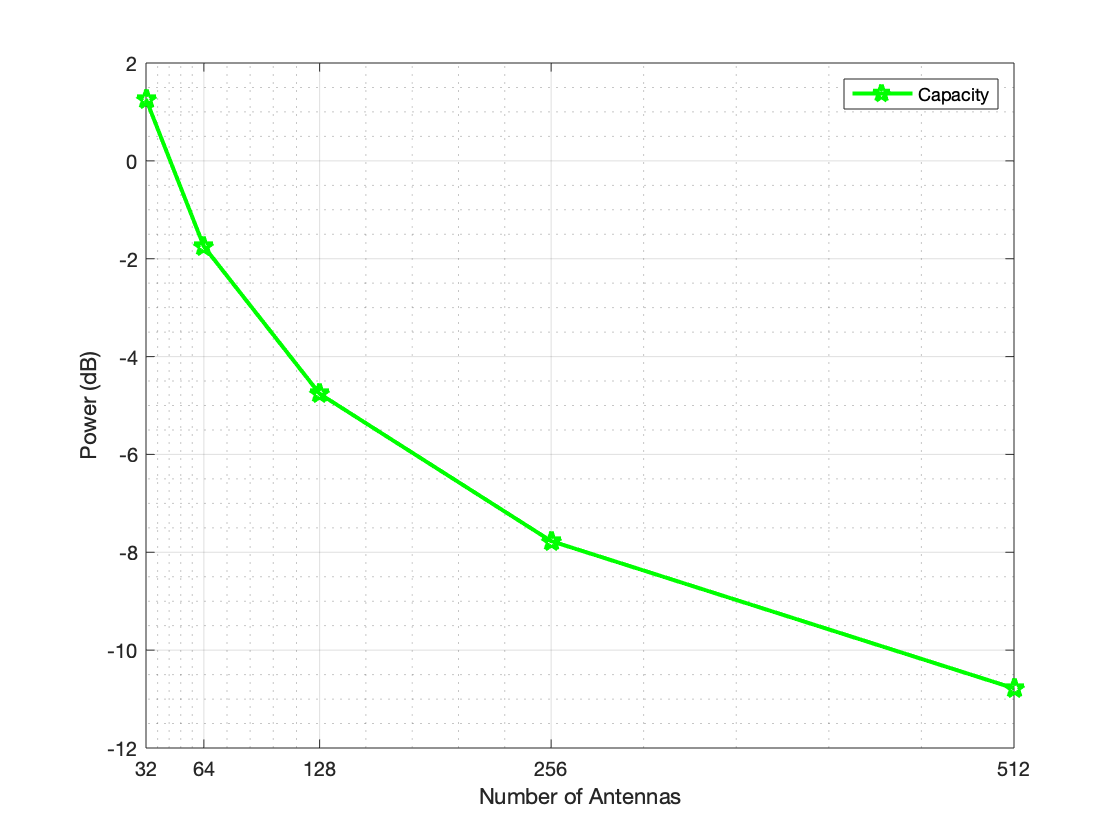

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_c = 'Capacity';
name_0 = 'Uncorrelated Channel';
name_1 = strcat('CMFP (1D), \alpha=', num2str(alpha));
name_2 = strcat('CMFP (1D), \eta=', num2str(eta), ', \mu=', angel);
name_3 = strcat('CMFP (2D), \alpha=', num2str(alpha));
name_4 = strcat('CMFP (2D), \eta=', num2str(eta), ', \mu=', angel);


figure;
plot(M, dBc, '-gp', 'DisplayName', name_c, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;

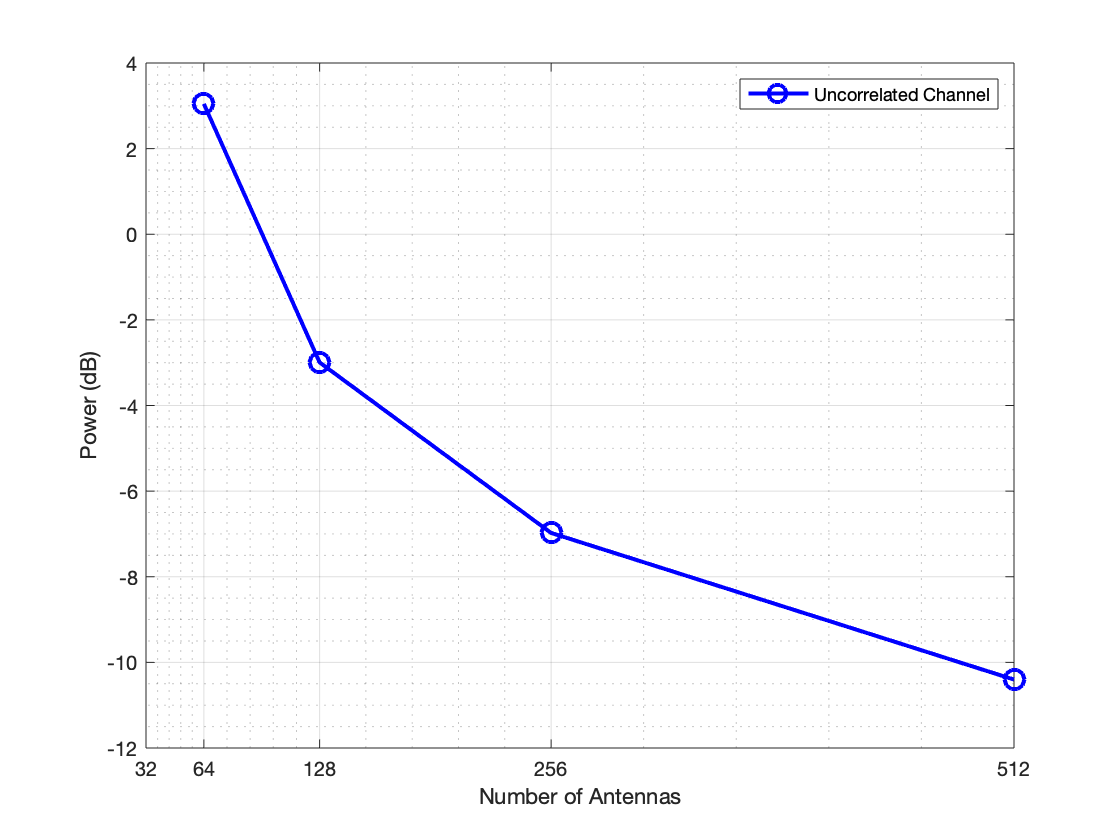


figure;
plot(M(2 : sample), dB0(2 : sample), '-bo', 'DisplayName', name_0, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;


%{
figure;
plot(M, dB1, '-bo', 'DisplayName', name_1, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;


figure;
plot(M, dB2, '-bo', 'DisplayName', name_2, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;


figure;
plot(M, dB3, '-bo', 'DisplayName', name_3, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend();
grid on;
grid minor;


figure;
plot(M, dB4, '-bo', 'DisplayName', name_4, 'MarkerSize', 10);

xlabel('Number of Antennas', 'fontsize', 10)
ylabel('Power (dB)', 'fontsize', 10)
set(gca, 'fontsize', 10)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(M);
xlim([M(1), M(sample)]);
legend()
grid on;
grid minor;
%}
